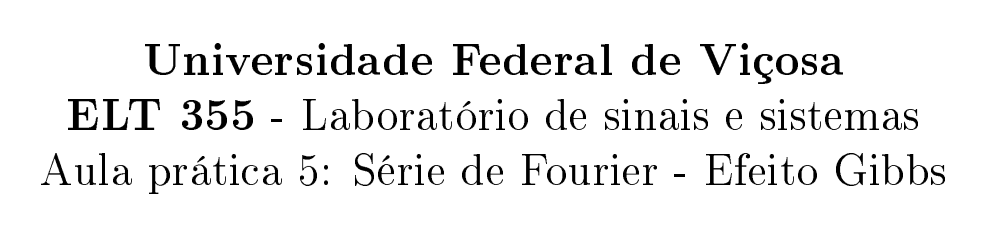

02/06/22

**Aluno:** Déric A. F. de Sales - 96718

clear all; close all; clc;

### Exercício 1 - Identificando e descrevendo o Efeito de Gibbs

Aula: [Fourier Series and Gibbs Phenomena [Matlab]](https://www.youtube.com/watch?v=98VixA3MjAc)

**Explicação:** 

Perto de pontos de descontinuidade, sempre que a série de Fourrier é truncada (não são somados infinitos termos), o fenômeno de Gibbs aparece. Ou seja, o fenômeno de Gibbs vai embora quando muitos termos da série são acrescentados, mas para poucos termos, sempre que a série de Fourrier é truncada para funções descotínuas será possivel notar o fonômeno.

Isso se dá pela forma com que a descontinuidade da função contruída é gerada. Para  gerar essa descontinuidade (ponto onde a derivada tende ao infinito) , é necessário somar diversas senoides e cossenoides em todas as frequências na propoção certa para que sua amplitude se some justamente nos pontos de descontinuidade, gerando a reta de inclinação de aproximadamente 90º. O efeito de Gibbs se dá quando não há termos suficientes de senoides e cossenoides em diferentes frequências sendo somados para que eles se cancelem logo após a descontinuidade, aparentando uma oscilação amortecida em torno do valor que deveria ser aproxomadamente constante (no caso da onda quadrada).

Plotando o módulo e a fase da função ck() lado a lado

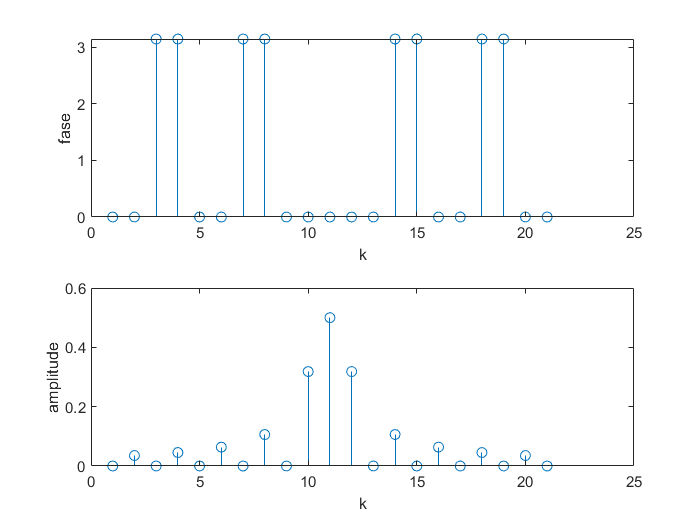

k = -10:1:10;

subplot(2,1,1)
stem(angle(ck(k))); xlabel('k'); ylabel('fase') 

subplot(2,1,2)
stem(abs(ck(k))); xlabel('k'); ylabel('amplitude') 

Reconstruindo uma onda quadrada pela Série de Fourrier, através dos termos ak da onda gerados pela função ck().

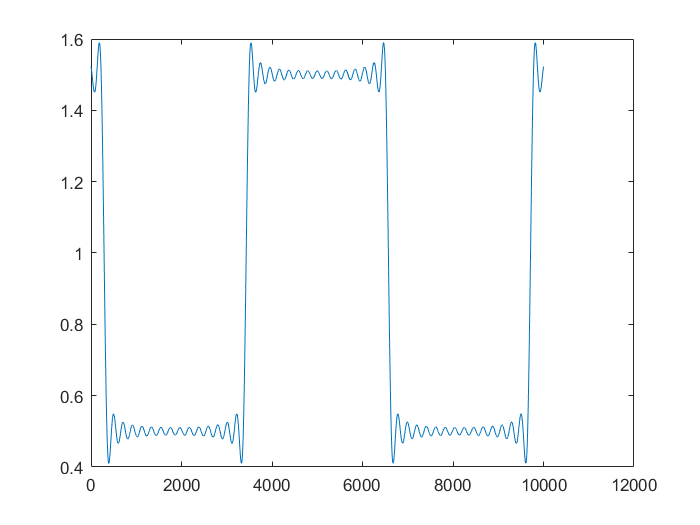

figure()

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.001:5; % vetor de tempo
kmax = 30; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)));
end

plot(x); 

Comparando com a função quadrada perfeita:

subplot(1,2,1);

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.01:5; % vetor de tempo
kmax = 50; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)));
end

plot(x); 
xlim([0 1000])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

hold on
x = (1/2)*square(t + pi/2);
plot(x+1);
xlim([1 1000])
ylim([0.3 1.7]);
hold off
title('aproximação com 50 termos')

Analisando a descontinuidade:

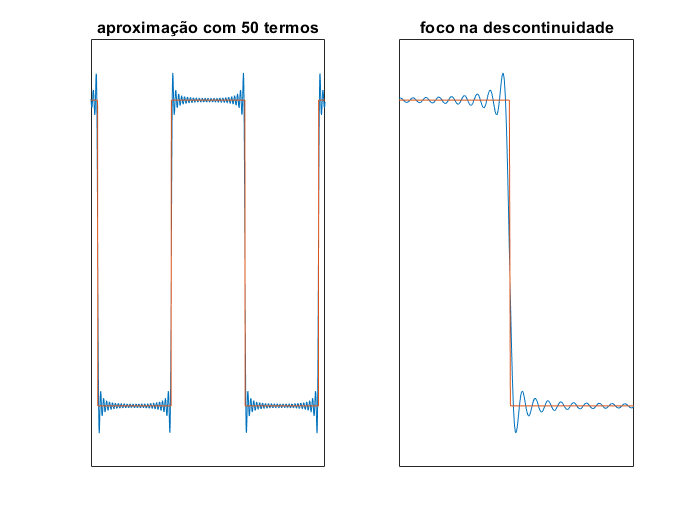

subplot(1,2,2)

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.01:5; % vetor de tempo
kmax = 50; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)));
end

plot(x); 
xlim([550 780])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

hold on
x = (1/2)*square(t + pi/2);
plot(x+1);
xlim([550 780])
ylim([0.3 1.7]);
hold off
title('foco na descontinuidade')

título da figura: Aproximação a uma onda quadrada através da Série de Fourier.

### Exercício 2 - Minimização do Efeito de Gibbs

1.  Síntese de Fourrier para 2, 5, 10, 50, 100 e 1000 termos:

para 2 termos: 

figure()

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 2; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)));
end

subplot(2,3,1)
plot(x); title('2 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 5 termos: 

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 5; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)));
end
subplot(2,3,2)
plot(x); title('5 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 10 termos: 

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 10; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)));
end
subplot(2,3,3) 
plot(x); title('10 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 50 termos: 

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 50; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)));
end
subplot(2,3,4) 
plot(x); title('50 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 100 termos: 

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 100; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)));
end
subplot(2,3,5)
plot(x); title('100 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 1000 termos: 

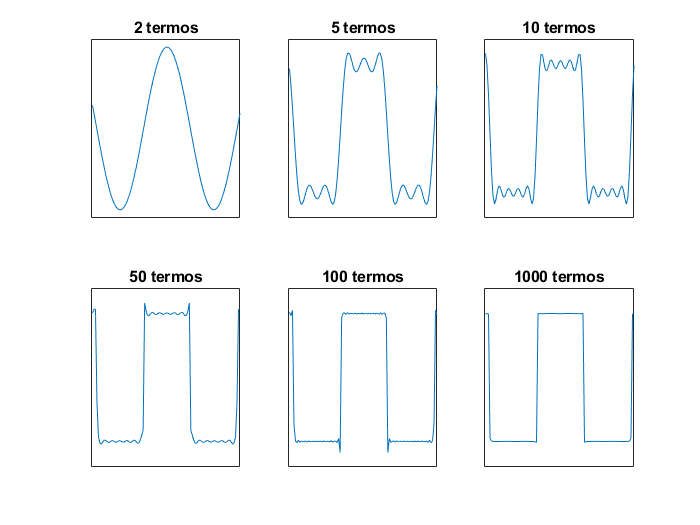

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 1000; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)));
end
subplot(2,3,6)
plot(x); title('1000 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

2.  Os métodos estudados consistem na multiplicação de uma expressão $k_r$ na expressão da série de Fourrier. 

a) utilizando o **janelamento de Fejer**


$$k_{r} = \frac{k_{max} - k}{k_{max}}$$


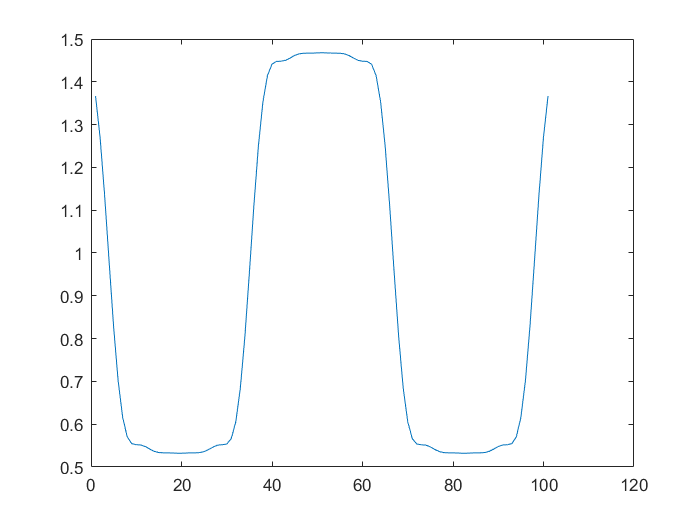

figure()

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 10; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(kmax-i)/kmax;
end

plot(x); 

para 2 termos: 

figure()

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 2; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(kmax-i)/kmax;
end

subplot(2,3,1)
plot(x); title('2 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 5 termos: 

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 5; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(kmax-i)/kmax;
end
subplot(2,3,2)
plot(x); title('5 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 10 termos: 

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 10; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(kmax-i)/kmax;
end
subplot(2,3,3) 
plot(x); title('10 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 50 termos: 

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 50; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(kmax-i)/kmax;
end
subplot(2,3,4) 
plot(x); title('50 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 100 termos: 

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 100; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(kmax-i)/kmax;
end
subplot(2,3,5)
plot(x); title('100 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 1000 termos: 

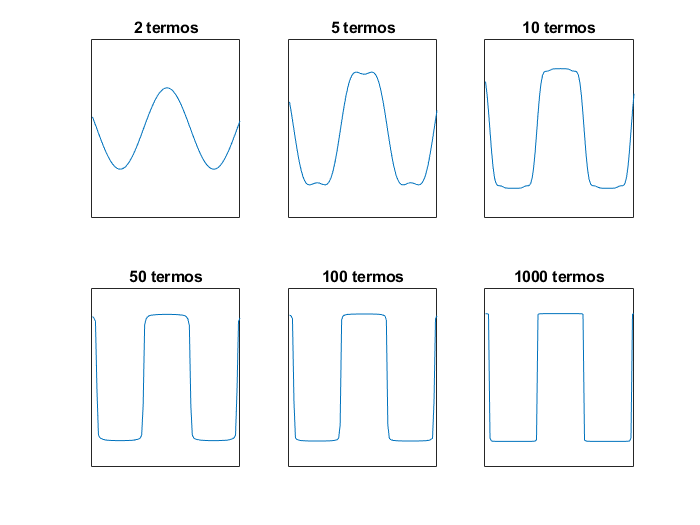

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 1000; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(kmax-i)/kmax;
end
subplot(2,3,6)
plot(x); title('1000 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

b) utilizando o **janelamento de Hamming**


$$w_r = 0.54 + 0.4 \cdot cos\left( \frac{k \cdot \pi}{k_{max}} \right)$$


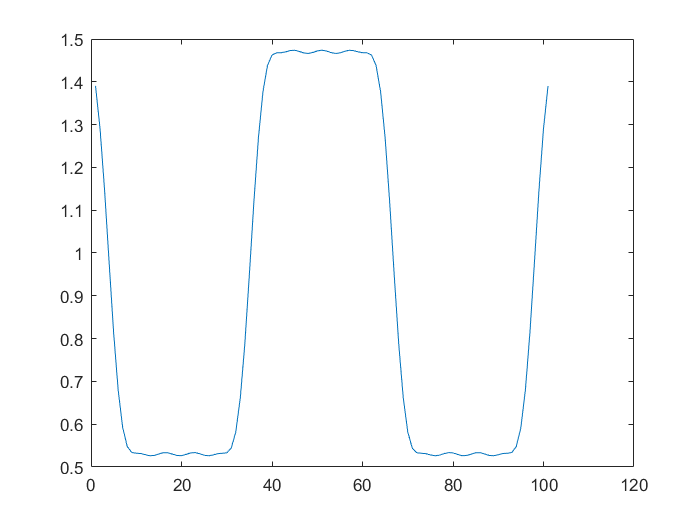

figure()

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 10; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(0.54 + 0.4*cos( (i*pi)/kmax ));
end

plot(x); 

para 2 termos: 

figure()

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 2; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(0.54 + 0.4*cos( (i*pi)/kmax ));
end

subplot(2,3,1)
plot(x); title('2 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 5 termos: 

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 5; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(0.54 + 0.4*cos( (i*pi)/kmax ));
end
subplot(2,3,2)
plot(x); title('5 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 10 termos: 

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 10; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(0.54 + 0.4*cos( (i*pi)/kmax ));
end
subplot(2,3,3) 
plot(x); title('10 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 50 termos: 

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 50; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(0.54 + 0.4*cos( (i*pi)/kmax ));
end
subplot(2,3,4) 
plot(x); title('50 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 100 termos: 

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 100; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(0.54 + 0.4*cos( (i*pi)/kmax ));
end
subplot(2,3,5)
plot(x); title('100 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

para 1000 termos: 

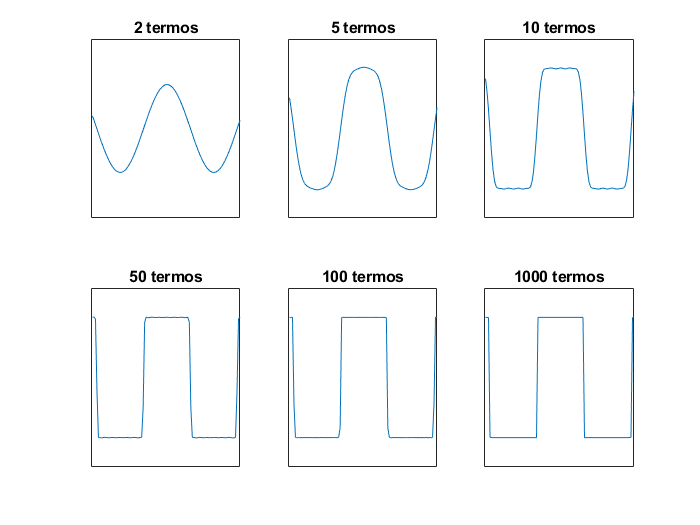

x = 1; % Ko -> primeiro elemento da série de Fourrier
wo = 1; % frequência angular
t = -5:0.1:5; % vetor de tempo
kmax = 1000; % número de termos na soma da série de Fourrier

for i = 1:kmax
   x = x + 2*abs(ck(i))*cos(i*wo.*t + angle(ck(i)))*(0.54 + 0.4*cos( (i*pi)/kmax ));
end
subplot(2,3,6)
plot(x); title('1000 termos')
xlim([0 100])
ylim([0.3 1.7]); set(gca,'XTick',[], 'YTick', [])

### Exercício 3 - Sintetizador de som

2. carregando o arquivo de áudio e o reproduzindo

figure()

load('trumpet.mat')   % salva o arquivo na variável y
sound(y,Fs)           % variável Fs da memória do Matlab

size_y = size(y,1);
fprintf('Comprimento do vetor y: %i', size_y )

Comprimento do vetor y: 28000

plotando curva do sinal puro

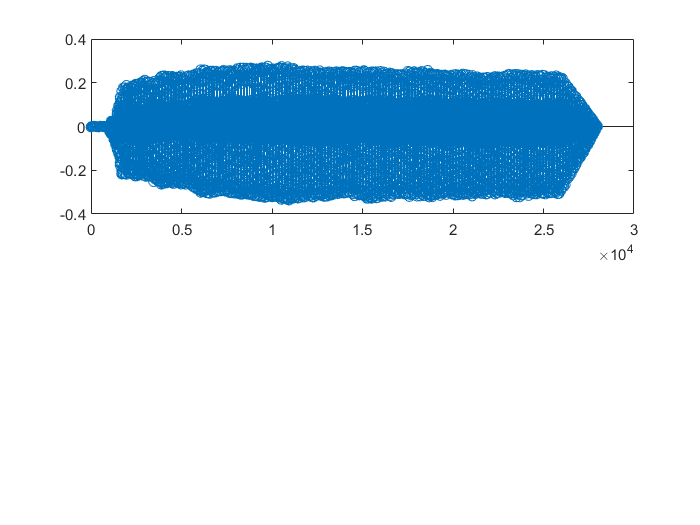

subplot(2,1,1);
graph_y = stem(y);

3 . Divindo o sinal em 3 janelas e o plotando

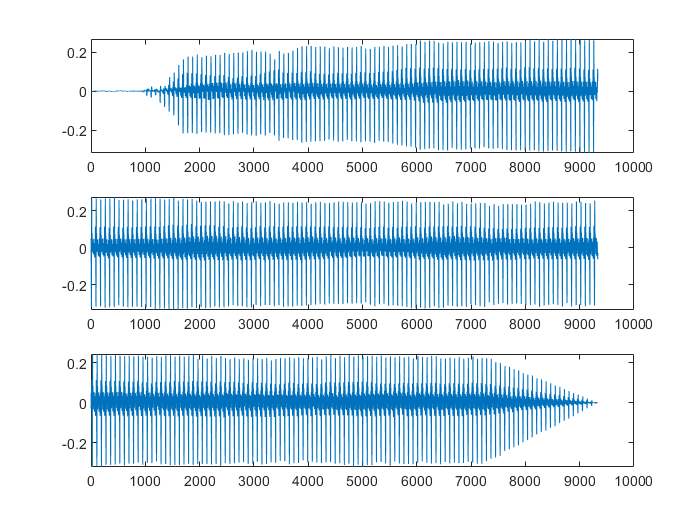

len_1over3 = floor(size_y/3);

subplot(3,1,1)
plot( y(1:len_1over3) ); 
subplot(3,1,2)
plot( y(len_1over3:(len_1over3*2)) );
subplot(3,1,3)
plot( y((len_1over3*2):size_y ));

4. Analisando o espectro do sinal

load('trumpet 30082019132152.mat');

Fs = 11025;
Y = fft(trumpet,512); %Realiza a transformada rápida de Fourier do sinal de som
Ymag = abs(Y(1:257)); %Calcula os módulos (harmônicos) do sinal de som 
Yfas = angle(Y(1:257)); %Calcula as fases do sinal de som
f = Fs*(0:256)/512;

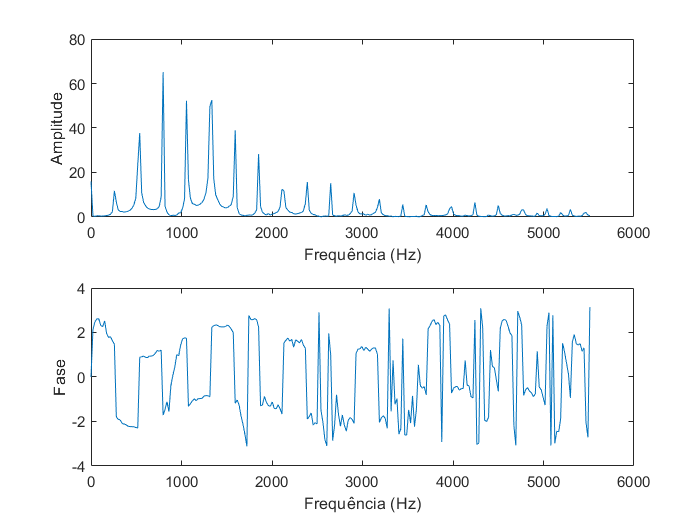

figure;
subplot(2,1,1), plot(f, Ymag); %title('Módulo e Fase do sinal trumpet');
xlabel('Frequência (Hz)'); ylabel('Amplitude');
subplot(2,1,2), plot(f, Yfas);
xlabel('Frequência (Hz)'); ylabel('Fase');

6,7,8 e 9 - Usando a função sintetizador()

[m, n] = sort(Ymag); %Organiza as magnitudes em ordem crescente
t = 0:1/Fs:1;
freq = f(n(253:257)); %Separa as frequências correspondentes às maiores magnitudes
mag = m(253:257); %Separa as maiores magnitudes
fas = Yfas(n(253:257)); %Separa as fases correspondentes às maiores magnitudes

X = sintetizador(t, freq, mag); %Chama a função que sintetiza o áudio (usando 5 harmônicos)
sound(X);

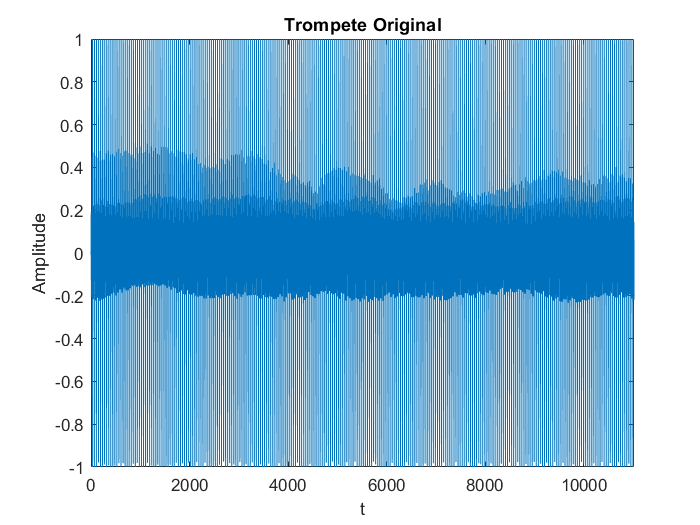

figure;
plot(trumpet); axis([0 11025 -1 1]); xlabel('t'); ylabel('Amplitude'); title('Trompete Original');

figure; subplot(2,1,1);
plot(X); axis([0 11025 -1 1]); 
xlabel('t'); ylabel('Amplitude'); title('sem fase');
%title('Trompete Sintetizado sem fase e com 5 harmônicos');
Y = sintetizadorfase(t, freq, mag, fas); %Chama a função que sintetiza o áudio com as fases (usando 5 harmônicos)
sound(Y);

subplot(2,1,2);
plot(Y); axis([0 11025 -1 1]);
xlabel('t'); ylabel('Amplitude'); title('com fase');

%title('Trompete Sintetizado com fase e 5 harmônicos');

10, 11 e 12.

**Para menos harmônicos**

t = 0:1/Fs:1;
freq = f(n(256:257));
mag = m(256:257);
fas = Yfas(n(256:257));

X = sintetizador(t, freq, mag); %Chama a função que sintetiza o áudio (usando 2 harmônicos)
sound(X);

figure; subplot(2,1,1);
plot(X); axis([0 11025 -1 1]); 
xlabel('t'); ylabel('Amplitude'); title('sem fase');
%title('Trompete Sintetizado sem fase e com 2 harmônicos');
Y = sintetizadorfase(t, freq, mag, fas); %Chama a função que sintetiza o áudio com as fases (usando 2 harmônicos)
sound(Y);

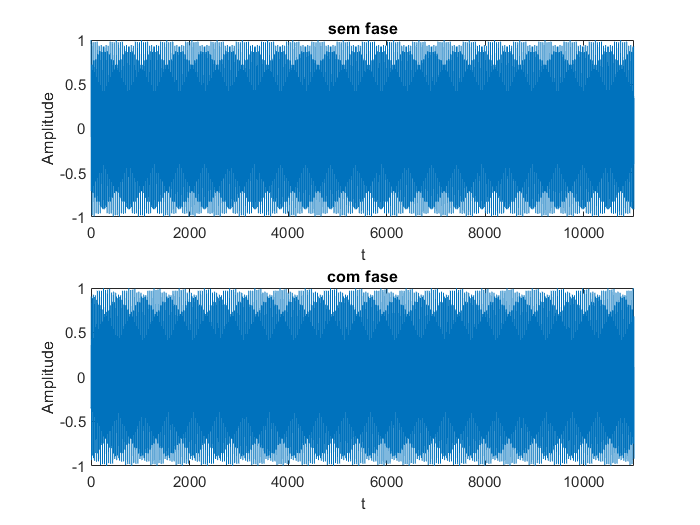

subplot(2,1,2);
plot(Y); axis([0 11025 -1 1]);
xlabel('t'); ylabel('Amplitude'); title('com fase');

%title('Trompete Sintetizado com fase e 2 harmônicos');

**Para mais harmônicos (todos)**

t = 0:1/Fs:1;
freq = f(n(1:257));
mag = m(1:257);
fas = Yfas(n(1:257));

X = sintetizador(t, freq, mag); %Chama a função que sintetiza o áudio (usando todos os harmônicos)
sound(X);

figure; subplot(2,1,1);
plot(X); axis([0 11025 -1 1]); 
xlabel('t'); ylabel('Amplitude'); title('sem fase');
%title('Trompete Sintetizado sem fase e com todos os harmônicos');
Y = sintetizadorfase(t, freq, mag, fas); %Chama a função que sintetiza o áudio com as fases (usando todos os harmônicos)
sound(Y);

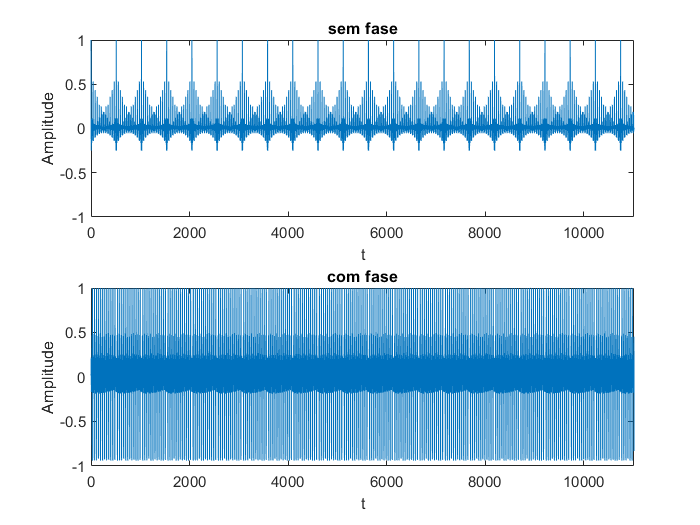

subplot(2,1,2);
plot(Y); axis([0 11025 -1 1]);
xlabel('t'); ylabel('Amplitude'); title('com fase');

%title('Trompete Sintetizado com fase e todos os harmônicos');